clear all
close all
run("wyliczanie_jacobianow_oraz_p_row.mlx")

ans = 0.0100

mwag_cal = -18.2574

close all



max_x = 0.0212;
initial_x = 0.013;
expected_z = 0.01;
KW = -[polyval(p_z,expected_z) polyval(p_v,expected_z) polyval(p_i,expected_z)];
Kw = -[polyval(p_z,expected_z)*max_x polyval(p_v,expected_z) polyval(p_i,expected_z)*3];


obsInfo = rlNumericSpec([3 1], LowerLimit=[-1 -1 -1]', UpperLimit=[ 1 1 1]');
actInfo = rlFiniteSetSpec([0:1/15:1]); 
obsInfo.Name = "observations";
obsInfo.Description = "position z,, velocity v, current";

actInfo.Name = "control";

env = rlSimulinkEnv("MODEL_neural","MODEL_neural/controller",obsInfo,actInfo);
env.ResetFcn = @start;

Ts = 5e-3;
Tf = 0.5;
rng(0)

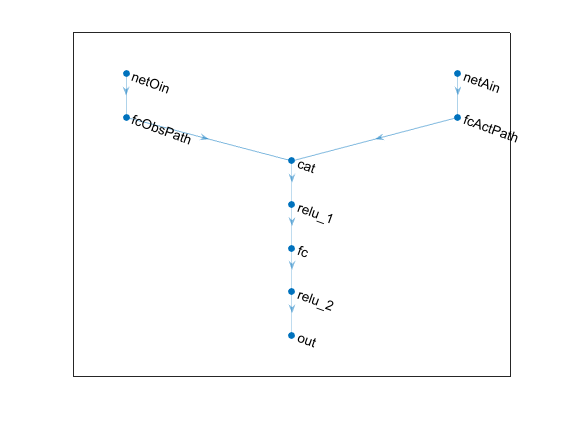

% Observation path
obsPath = [
    featureInputLayer(prod(obsInfo.Dimension),Name="netOin")
    fullyConnectedLayer(64, Name = "fcObsPath")
    ];

% Action path
actPath = [
    featureInputLayer(prod(actInfo.Dimension),Name="netAin")
    fullyConnectedLayer(64,Name="fcActPath")
    ];

% Common  path (concatenate inputs along dim #1)
commonPath = [
    concatenationLayer(1,2,Name="cat")
    reluLayer
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(1,Name="out")
    ];
net = dlnetwork;
net = addLayers(net,obsPath);
net = addLayers(net,actPath);
net = addLayers(net,commonPath);
net = connectLayers(net,"fcObsPath","cat/in1");
net = connectLayers(net,"fcActPath","cat/in2");
plot(net)

net = initialize(net);
summary(net)


   Initialized: true

   Number of learnables: 4.5k

   Inputs:
      1   'netOin'   3 features
      2   'netAin'   1 features




critic = rlQValueFunction(net, ...
    obsInfo, ...
    actInfo, ...
    ObservationInputNames="netOin", ...
    ActionInputNames="netAin");

getValue(critic,{rand(obsInfo.Dimension)},{rand(actInfo.Dimension)})

ans = single
0.0303

agent = rlDQNAgent(critic)

agent =   rlDQNAgent with properties:

        ExperienceBuffer: [1×1 rl.replay.rlReplayMemory]
            AgentOptions: [1×1 rl.option.rlDQNAgentOptions]
    UseExplorationPolicy: 0
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlFiniteSetSpec]
              SampleTime: 1


agent.AgentOptions.UseDoubleDQN=false;
agent.UseExplorationPolicy = true;
agent.AgentOptions.TargetUpdateMethod="periodic";
agent.AgentOptions.TargetUpdateFrequency=1;
agent.AgentOptions.ExperienceBufferLength=10000;
agent.AgentOptions.SampleTime = Ts;
agent.AgentOptions.DiscountFactor=0.99;
agent.AgentOptions.MiniBatchSize=128;

agent.AgentOptions.CriticOptimizerOptions.LearnRate=1e-3;
agent.AgentOptions.CriticOptimizerOptions.GradientThreshold=100;
agent.AgentOptions.EpsilonGreedyExploration.Epsilon = 1;
agent.AgentOptions.EpsilonGreedyExploration.EpsilonDecay = 2.5e-4;

getAction(agent,{rand(obsInfo.Dimension)})

ans = 1×1 cell array
    {[0.2000]}


trainOpts = rlTrainingOptions(...
    MaxEpisodes=15000, ...
    MaxStepsPerEpisode=ceil(Tf/Ts), ...
    Plots="training-progress", ...
    Verbose=false, ...
    StopTrainingCriteria="EpisodeReward", ...
    StopTrainingValue=-10 ...
    );

    trainingOpts.UseParallel = true;
    trainingOpts.ParallelizationOptions.Mode = "sync";
    trainingOpts.ParallelizationOptions.StepsUntilDataIsSent = -1;
% agent evaluator
 evl = rlEvaluator(EvaluationFrequency=25,NumEpisodes=5);
doTraining = 1;

if doTraining
    trainingStats = train(agent,env,trainOpts,Evaluator=evl);
    save("agent.mat","agent")
end